addpath("helpers")

data_src = "C:\Users\kpiec\OneDrive - Politechnika Łódzka\Studia\2Sem3\magisterka\pomiary\IWR1843BOOST\hall-end_side_run_0\measurement_002";
iwr = IWR1843(data_src);
load(data_src+"\RD.mat", "-mat");

Error using load
Unable to find file or directory "C:\Users\kpiec\OneDrive - Politechnika Łódzka\Studia\2Sem3\magisterka\pomiary\IWR1843BOOST\hall-end_side_run_0\measurement_002\RD.mat".

srcParts = split(data_src, "\");
dataName = join(srcParts(end-1:end), "-");
clear srcParts
[rangeBins, dopBins, numFrames] = size(DATA);

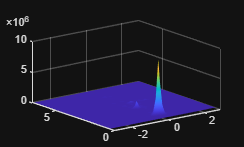

bgFilterFrameCount = 100;
showFrame=554;

BG = bgFilter(DATA(:, :, 1), bgFilterFrameCount);

for frN = max([showFrame-BG.length 1]):showFrame-1
    BG.addSample(DATA(:, :, frN));
end
data = BG.addSampleNoBg(DATA(:, :, showFrame), 0.98);
data(data<0)=0;
figure(1);
show3D(dopGrid, rngGrid, DATA(:, :, showFrame));

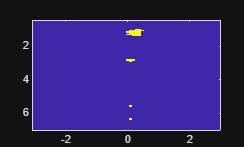

% [rangeBands dopplerBands]
guardCells = [5 6];
trainCells = [3 4];
fap = 1e-6;
method = "GOCA";

tet=data;
[dets,mask] = runCFAR2D(guardCells,trainCells,fap,method, tet);

figure(2);
plt = tet;
plt(~mask) = 0;
imagesc(dopGrid, rngGrid, mask);

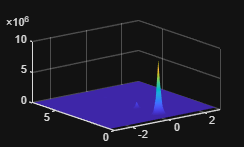

figure(3);
show3D(dopGrid, rngGrid, plt);

% figure(3);
% targets = [dopGrid(dets(2, :)); rngGrid(dets(1, :))];
% [X, Y] = pol2cart(deg2rad(targets(1, :)), targets(2, :));
% plot(Y, X, '*',"MarkerEdgeColor","r");
% ylim([0 rngGrid(end)]);
% xlim([-3, 3]);